# Figures 1,2,3

Chapter: Visual Encoding Authors: Wandell, Brainard, Cottaris Editor: Spitschan

Include ISETBio on your path.

%{
thisDir = '/Volumes/GoogleDrive/My Drive/Papers/Book Chapters/2021 Circadian Functions (Spitschan)';
chdir(thisDir)
%}

## Figure 1:  Display radiance

A display emits a spectral radiance from each small spatial region $r(x,y)$. Within each region (pixel) the display radiance is the weighted sum of the emissions of the display primaries (plus potentially some amount of reflected ambient light, not shown). The radiance from each region is the weighted sum of the primaries, and the weights depend on the image. The rays are emitted in many directions, and only a small fraction of the ray bundle reaches the cornea, forming the incident light field. The physiological optics (cornea and lens) transform the light at the cornea into the retinal irradiance. The lens of the eye accommodates to focus the relevant portion of the image at the cone inner segment layer.

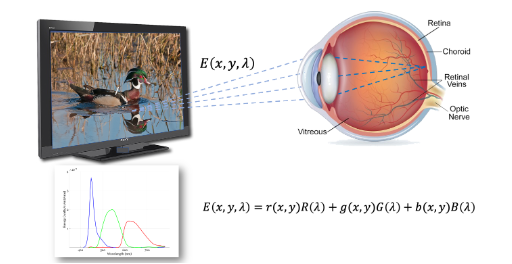

% Create the scene from the file
displayName = 'LCD-Apple';
scene = sceneFromFile('woodDuck.png','rgb',100,displayName);

[vcReadImage] Assuming an 8bit image and a 10 bit LUT


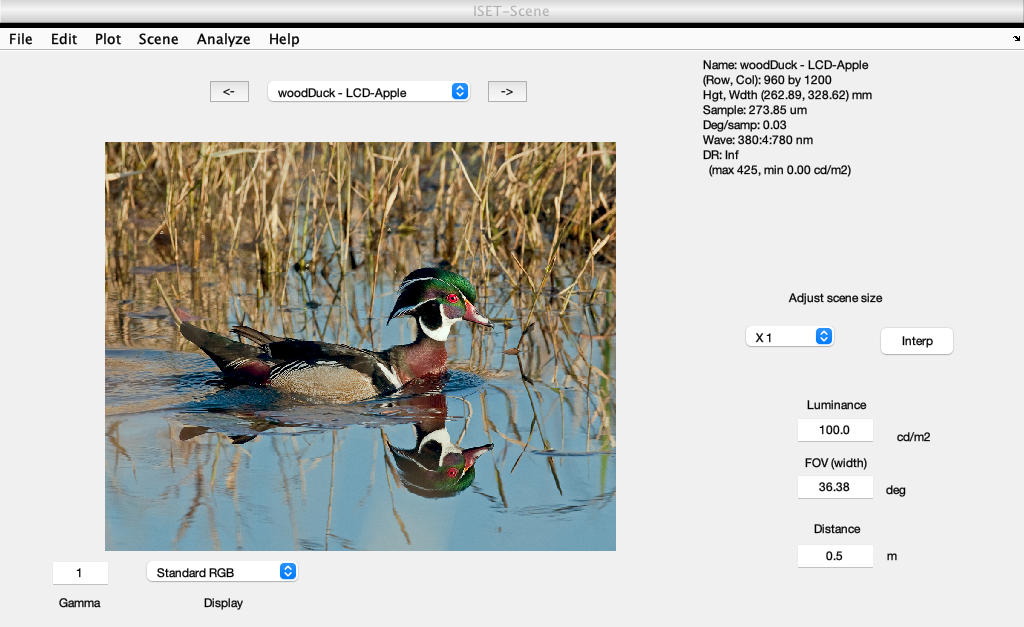

sceneWindow(scene);

We picked a rectangular region for the figure. You can select another region this way:

Or you can use the interactive menus in the window.

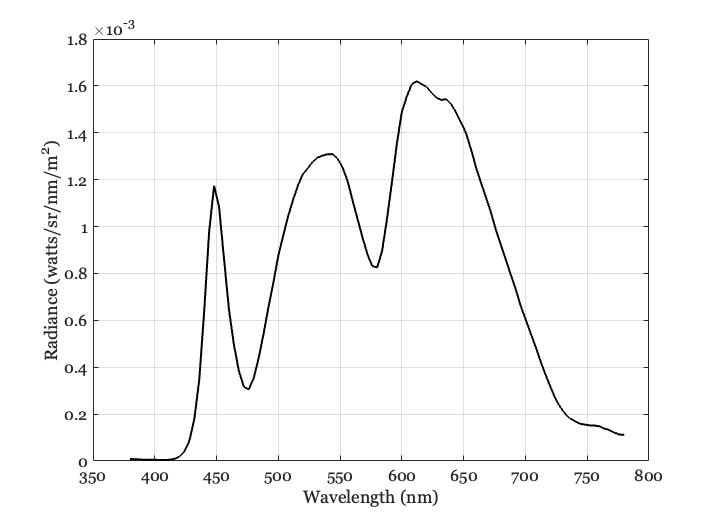

rect = [193 93 120 190];
scenePlot(scene,'radiance energy roi',rect);
thisAx = gca;
thisAx.Children.LineWidth = 2;
thisAx.Children.Color = 'k';

## Figure 2: The natural radiance display

For most displays the emitted spectral radiance is unlike the spectral radiance observed in nature. It can be useful to convert an RGB image into a scene spectral radiance that matches the appearance on a standard display (sRGB) but that also has a natural spectral radiance. ISETBio includes a method, based on a theoretical display, that accomplishes this. See text for details.}

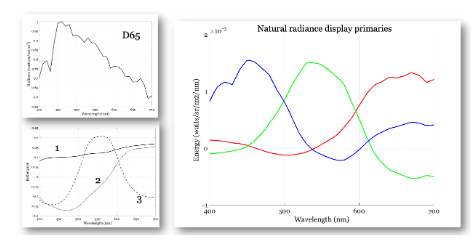

displayName = 'reflectance-display';
scene = sceneFromFile('woodDuck.png','rgb',100,displayName);
sceneWindow(scene);

scenePlot(scene,'radiance energy roi',roi);
thisAx = gca;
thisAx.Children.LineWidth = 2;
thisAx.Children.Color = 'k';

## Now a pretty standard Samsung display

displayName = 'OLED-Samsung';
scene = sceneFromFile('woodDuck.png','rgb',100,displayName);
sceneWindow(scene);

scenePlot(scene,'radiance energy roi',roi);
thisAx = gca;
thisAx.Children.LineWidth = 2;
thisAx.Children.Color = 'k';

## Now the displays themselves

wave = 400:1:700;
wSamples = 400:50:700;
displayName = 'LCD-Apple';
thisDisplay = displayCreate(displayName);
displayPlot(thisDisplay,'spd');
set(gca,'xtick',wSamples,'ytick',(1:4)*1e-3);

displayName = 'reflectance-display';
thisDisplay = displayCreate(displayName);
displayPlot(thisDisplay,'spd');
set(gca,'xtick',wSamples,'ytick',(-1:4)*1e-3);
p = xaxisLine;
p.LineWidth = 0.5;

basis = ieReadSpectra('reflectanceBasis.mat',wave);
basis(:,1) = -1*basis(:,1);
hdl = plotReflectance(wave,basis(:,1:3));

thisAx = get(hdl,'CurrentAxes'); p = thisAx.Children;
p(1).Color = 'k';
p(2).Color = 'k'; p(2).LineStyle = '-.';
p(3).Color = 'k'; p(3).LineStyle = '--';

thisLine = xaxisLine;
lineShade = [0.7 0.7 0.7];
thisLine.LineWidth = 2; thisLine.LineStyle = '-'; thisLine.Color = lineShade;
title('');

d65 = ieReadSpectra('d65.mat',wave);
d65 = d65/max(d65(:));
hdl = plotRadiance(wave,d65);
thisAx = get(hdl,'CurrentAxes'); p = thisAx.Children;
for ii=1:numel(p)
    p(ii).Color = 'k';
end
title('');

% Calibration files are stored in data/displays/
% d = displayCreate('OLED-Samsung');

%{
displayName = 'reflectance-display';
scene = sceneFromFile('stanfordQuadEntryLowRes.png','rgb',100,displayName);
sceneWindow(scene);
%}

## Illustrate text

scene = sceneFromFile('text.png','rgb',50,'reflectance-display');
sceneWindow(scene);